# Analyze specific experiments using linear (background) digging model and no background (scale factor) model -  new UseNests

use 'dAdtModel2.m' function: [MdAdt,Am] = dAdtModel2(ta,tb,m,b,dPdt,A0)

for both models use: ta = -48 and tb = 0

for background model use m=1.895 and b=0.142

for scale factor model use m=2.039 and b=0.

**Need new way to evaluate model prediction for between modeled and real dAdt**

because correlation in independent of scale factor, need something in addition. RMSE doesn't cancel out positive and negative errors so not useful. RMSE for final result is problematic as it can vary greatly only due to few misses in dAdt modeling.

Use R-squared instead of correlation coefficient, to get proportion of explained variance.

**USE MAE (mean absolute error) instead of RMSE.**

**TRY: **percent of data points in modeled Area with absolute error less than the MAE + 1 SD == ACCURACY

which is 3.9346 cm^2/day. Round up to 4.

*For mean tArea get ****87.23%***

# Get R-squared and %Accurate for all use nests

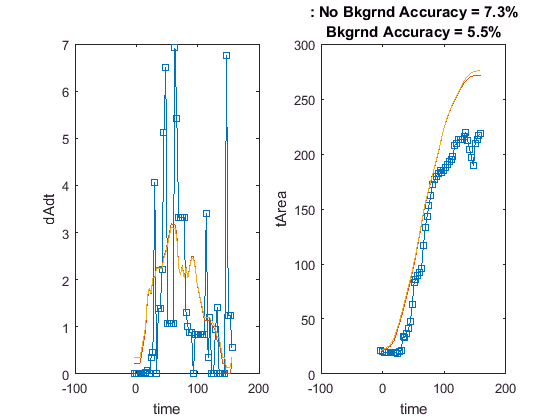

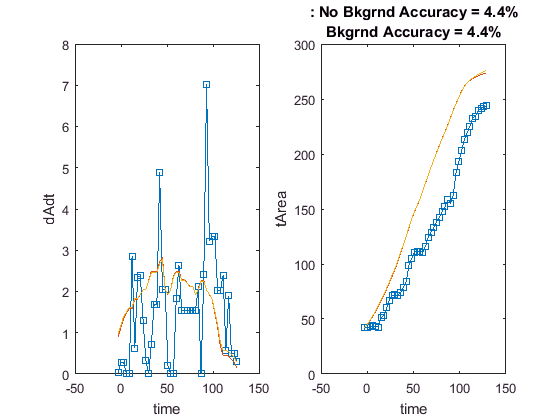

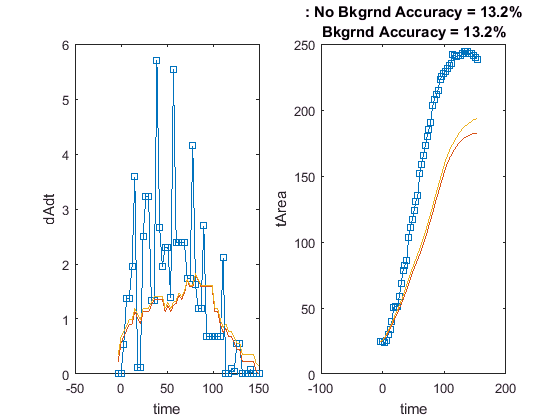

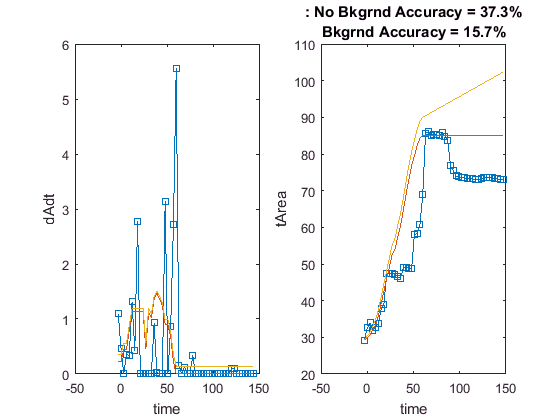

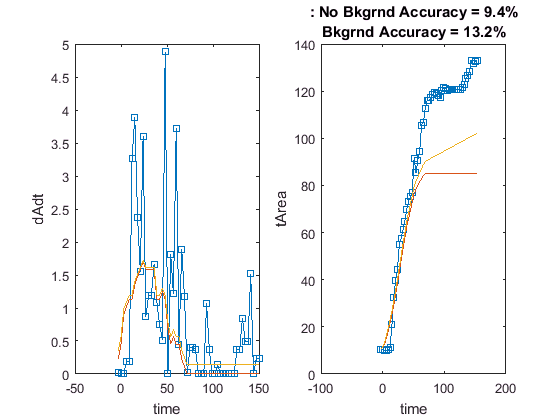

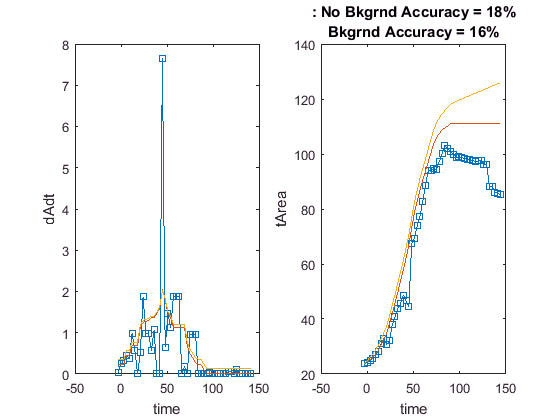

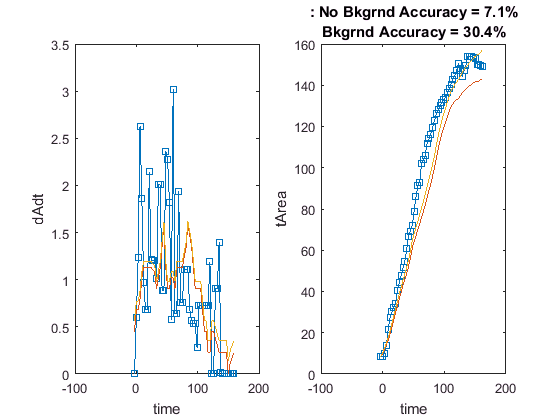

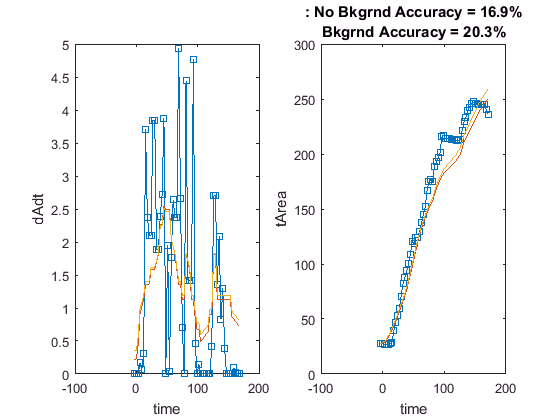

UseNests = [3:6,8,11:13,15:18,20,22,25:29];
%% Get pop and A data per nest k
load('Data\MeanData\fArea_Pop_All_S.mat','PopBin','t')
load('Data\MeanData\tArea_All_S.mat','tAbin')

EvalTable = table;

for i=1:numel(UseNests)
    k = UseNests(i);
    t0 = find(t==0)-1;
    tend = find(~isnan(tAbin(:,k)),1,'last');
    time = t(t0:tend);
    tA = tAbin(t0:tend,k);
    dAdt = diff(tA)./3;
    dAdt(dAdt<0) = 0; % filter out negative digging rates, and replace them as 0
    pop = PopBin(t0:tend,k);
    dPdt = diff(pop)./3;
    
    [MdAdt1,Am1] = dAdtModel2(-48,0,2.039,0,dPdt,tA(1));
    [MdAdt2,Am2] = dAdtModel2(-48,0,1.895,0.142,dPdt,tA(1));
    
    EvalTable.tag(i) = k;%{['F',num2str(k)]};
    
    EvalTable.NoB_Rsq(i) = 1-(sum((dAdt-MdAdt1).^2)/numel(dAdt))/var(dAdt,1);
    AbsE1 = abs(tA-Am1);
    EvalTable.NoB_MAE(i) = mean(AbsE1);
    EvalTable.NoB_Accuracy(i) = sum(AbsE1<=4)/numel(AbsE1);
    
    EvalTable.B_Rsq(i) = 1-(sum((dAdt-MdAdt2).^2)/numel(dAdt))/var(dAdt,1);
    AbsE2 = abs(tA-Am2);
    EvalTable.B_MAE(i) = mean(AbsE2);
    EvalTable.B_Accuracy(i) = sum(AbsE2<=4)/numel(AbsE2);
    
    figure
    subplot(1,2,1)
    plot(time(1:end-1),dAdt,'-s',time(1:end-1),MdAdt1,time(1:end-1),MdAdt2)
    xlabel('time')
    ylabel('dAdt')
    %title({[EvalTable.tag{i},': No Bkgrnd Model Rsq = ',num2str(round(EvalTable.NoB_Rsq(i),2))];...
      %  ['Bkgrnd Model Rsq = ',num2str(round(EvalTable.B_Rsq(i),2))]})
    
    subplot(1,2,2)
    plot(time,tA,'-s',time,Am1,time,Am2)
    xlabel('time')
    ylabel('tArea')
    %legend({'Results','No Bkgrnd','Bkgrnd'},'Location','southoutside')
    title({[': No Bkgrnd Accuracy = ',num2str(100.*round(EvalTable.NoB_Accuracy(i),3)),'%'];...
        ['Bkgrnd Accuracy = ',num2str(100.*round(EvalTable.B_Accuracy(i),3)),'%']})
    
end

Mean accuracy

Mean_NoB_accu = mean(EvalTable.NoB_Accuracy)

Mean_NoB_accu = 0.1756

Mean_NoB_MAE = mean(EvalTable.NoB_MAE)

Mean_NoB_MAE = 22.0581

Mean_B_accu = mean(EvalTable.B_Accuracy)

Mean_B_accu = 0.1826

Mean_B_MAE = mean(EvalTable.B_MAE)

Mean_B_MAE = 21.3314

**Conclusion: **

**general low accuracy overall.**

**Need to think of all different reasons for change in area, digging rate is only one contributer.**

**Slightly better performance (accuracy and MAE) in background model.**

****Simpler to just take "no-background" model, as easier to explain without constant digging, and almost negligible improvement.**

**if I dp try to explain the bkgrnd digging, then maybe its a probabelistic behavior, but then from where do I get the probability function of how likely the ants dig unrelated to changes in population, area or density?**